Computer Controlled Systems - Control Design Project - Suspension system of a bus

Gyurcsik Máté - U3U9W1

Fegyó Anna - CLPL81

**TASK DESCRIPTION:**

You have a model of a linear time-invariant system, resulting from a real-world engineering problem, with input, output and state variables. 

Your task is the analysis and control of the chosen system, based on the guidelines below. Choosing a suitable initial state, input, control objective (e.g. stabilization, reference tracking), etc. for your model is part of the task. Example parameters were given (or already substituted into the equations) for your model - you can use these for simulations if you want.

All ﬁgures and calculations should be done in MATLAB (hint: there is no need to reinvent the wheel - there are plenty of useful functions and toolboxes for system control and symbolic calculations which you can use. Google them, look at tutorials, try to understand how you can make use of them). As some of the models are quite complicated, there is no need to calculate anything by hand. 

The MATLAB code should be submitted as part of the assignment, so please clean it up when you are ﬁnished and try to make it understandable.

Besides the code, a report should be submitted in PDF format, where you present and explain your work (you can include ﬁgures, formulas, results - anything you feel necessary).

In your work, you should cover the following topics:

**Analysis:**

- State-space model

- Input-output model: transfer function, impulse respponse function

- Response of the system for a given input

- Stability (Lyapunov as well)

- Controllability, Observability

- Discretization

**Control: **(you should choose 3 of the 5 points below)

- PID

- Pole placement, State estimator

- LQR control (continuous time)

- LQR control (discrete time)

- Deadbeat (discrete time)

**OUR TASK: 6. SUSPENSION SYSTEM OF A BUS**

Designing an automotive suspension system is an interesting and challenging control problem. When the suspension system is designed, a 1/4 model (one of the four wheels) is used to simplify the problem to a 1-D multiple spring-damper system. A diagram of this system is shown below. This model is for an active suspension system where an actuator is included that is able to generate the control force u to control the motion of the bus body.

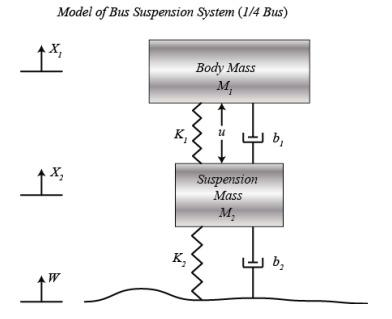

We have the following variables:

syms s
syms u w dw
%syms m1 m2 k1 k2 b1 b2
syms dv1 dv2 
syms v1 v2 x1 x2
syms y

Where w is a disturbance input representing the surface of the road (see figure).

By introducint a variable dv1 = v1 and dv2 = v2, the state-space equation with four state variables, and one output (y = x1 - x2) can be easily derived.

We have the parameter values using SI units:

m1=2500 

m1 = 2500

m2=320 

m2 = 320

k1=80000 

k1 = 80000

k2=500000

k2 = 500000

b1=350 

b1 = 350

b2=15020

b2 = 15020


y=x1-x2

$$y = x_{1}-x_{2}$$

Where m1 is the 1/4 bus body mass, m2 is the suspension mass, k1 is the spring constant of the suspension system, k2 is the spring constant of the wheel and tire, b1 is the damping constant of the suspension system and b2 is the damping constant of the wheel and tire.

The equations for the above model can be written as:

eqvt_1=[m1*dv1==-b1*(v1-v2)-k1*(x1-x2)+u]

$$eqvt\_1 = 2500\,{\mathrm{dv}}_{1}=u-350\,v_{1}+350\,v_{2}-80000\,x_{1}+80000\,x_{2}$$

eqvt_2=[m2*dv2==b1*(v1-v2)+k1*(x1-x2)+b2*(dw-v2)+k2*(w-x2)+u]

$$eqvt\_2 = 320\,{\mathrm{dv}}_{2}=15020\,\mathrm{dw}+u+350\,v_{1}-15370\,v_{2}+500000\,w+80000\,x_{1}-580000\,x_{2}$$

ANALYSIS - STATE-SPACE MODEL

%We express dv1 with the state variables
eqvt_dv1=solve(eqvt_1,dv1)

$$eqvt\_dv1 = \frac{u}{2500}-\frac{7\,v_{1}}{50}+\frac{7\,v_{2}}{50}-32\,x_{1}+32\,x_{2}$$

simplify(eqvt_dv1)

$$ans = \frac{u}{2500}-\frac{7\,v_{1}}{50}+\frac{7\,v_{2}}{50}-32\,x_{1}+32\,x_{2}$$

%We express dv2 with the state variables
eqvt_dv2=solve(eqvt_2,dv2)

$$eqvt\_dv2 = \frac{751\,\mathrm{dw}}{16}+\frac{u}{320}+\frac{35\,v_{1}}{32}-\frac{1537\,v_{2}}{32}+\frac{3125\,w}{2}+250\,x_{1}-\frac{3625\,x_{2}}{2}$$

simplify(eqvt_dv2)

$$ans = \frac{751\,\mathrm{dw}}{16}+\frac{u}{320}+\frac{35\,v_{1}}{32}-\frac{1537\,v_{2}}{32}+\frac{3125\,w}{2}+250\,x_{1}-\frac{3625\,x_{2}}{2}$$

First we have to define our A, B, C, D matrices for the state space representation.

eqvt_dx1=v1

$$eqvt\_dx1 = v_{1}$$

eqvt_dx2=v2

$$eqvt\_dx2 = v_{2}$$

syms A B C D

A=[0 0 1 0;
    0 0 0 1;
    -k1/m1 k1/m1 -b1/m1 b1/m1;
    k1/m2 -k2/m2-k1/m2 b1/m2 -b2/m2+b1/m2]

A = 	1.0e+03 *

         0         0    0.0010         0
         0         0         0    0.0010
   -0.0320    0.0320   -0.0001    0.0001
    0.2500   -1.8125    0.0011   -0.0458


B=[0 0 0;
    0 0 0;
    1/m1 0 0;
    0 b2/m2 b2/m2]

B =          0         0         0
         0         0         0
    0.0004         0         0
         0   46.9375   46.9375


C=[1 -1 0 0]

C =      1    -1     0     0


D=[0 0 0]

D =      0     0     0


Then we have to define our state space model, according to the followings:

- state equation: dv1 = Ax + Bu

- output equation: y = Cx + Du

ANALYSIS - INPUT-OUTPUT MODEL: TRANSFER FUNCTION, IMPULSE RESPONSE FUNCTION

Our second task is to define the transfer function based on the followings:

- the transfer function H(s) is the Laplace transform of the output Y(s) divided by the Laplace transform of the input U(s).

- the transfer function can be calculated from the state space matrices: $H(s) = C(sI-A)^{-1} B+D$

I_matrix=diag(ones(4,1))
H=C*inv(s*I_matrix-A)*B
simplify(H)

Then we have to determine the impulse response function which is the inverse Laplace transform of the transfer function.

h=ilaplace(H)

I_matrix =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


sys = ss(A,B,C,D)

$$H = \begin{array}{l} \left(\begin{array}{ccc} \frac{32\,s^{2}+1467\,s+58000}{100\,\sigma_{1}}-\frac{7\,s+1600}{20\,\sigma_{1}} & \frac{751\,\left(7\,s+1600\right)}{\sigma_{1}}-\frac{751\,\left(50\,s^{2}+7\,s+1600\right)}{\sigma_{1}} & \frac{751\,\left(7\,s+1600\right)}{\sigma_{1}}-\frac{751\,\left(50\,s^{2}+7\,s+1600\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=800\,s^{4}+36787\,s^{3}+1480612\,s^{2}+1320600\,s+40000000 \end{array}$$

impulse(sys)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{2\,\left(4\,s^{2}+179\,s+6250\right)}{25\,\sigma_{2}} & \sigma_{1} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{37550\,s^{2}}{\sigma_{2}}\\ \sigma_{2}=800\,s^{4}+36787\,s^{3}+1480612\,s^{2}+1320600\,s+40000000 \end{array}$$

ANALYSIS - RESPONSE OF THE SYSTEM FOR A GIVEN INPUT

%ide ki kene talalni valami jot

ANALYSIS - STABILITY (LYAPUNOV AS WELL)

First we want to decide the stability considering the poles of the transfer function. We need their real part to be negative in order to determine stability.

%p = poles(H)
%logical(p<zeros(length(p),1))

$$h = \begin{array}{l} \left(\begin{array}{ccc} \frac{8\,\sigma_{1}}{25}+500\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}}{3200\,{\sigma_{2}}^{3}+110361\,{\sigma_{2}}^{2}+2961224\,\sigma_{2}+1320600}\right)+\frac{358\,\left(\sum_{k=1}^{4}\frac{{\mathrm{e}}^{\sigma_{2}\,t}\,\sigma_{2}}{2961224\,\sigma_{2}+110361\,{\sigma_{2}}^{2}+3200\,{\sigma_{2}}^{3}+1320600}\right)}{25} & -37550\,\sigma_{1} & -37550\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{4}\frac{{\mathrm{e}}^{t\,\sigma_{2}}\,{\sigma_{2}}^{2}}{3200\,{\sigma_{2}}^{3}+110361\,{\sigma_{2}}^{2}+2961224\,\sigma_{2}+1320600}\\ \sigma_{2}=\mathrm{root}\left({s_{3}}^{4}+\frac{36787\,{s_{3}}^{3}}{800}+\frac{370153\,{s_{3}}^{2}}{200}+\frac{6603\,s_{3}}{4}+50000,s_{3},k\right) \end{array}$$

disp("The system is stable:")
isstable(sys)


sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3     -32      32   -0.14    0.14
   x4     250   -1813   1.094  -45.84
 
  B = 
           u1      u2      u3
   x1       0       0       0
   x2       0       0       0
   x3  0.0004       0       0
   x4       0   46.94   46.94
 
  C = 
       x1  x2  x3  x4
   y1   1  -1   0   0
 
  D = 
       u1  u2  u3
   y1   0   0   0
 
Continuous-time state-space model.



Then we can check the stability considering the eigenvalues of matrix A. We need their real part to be negative in order to determine stability.

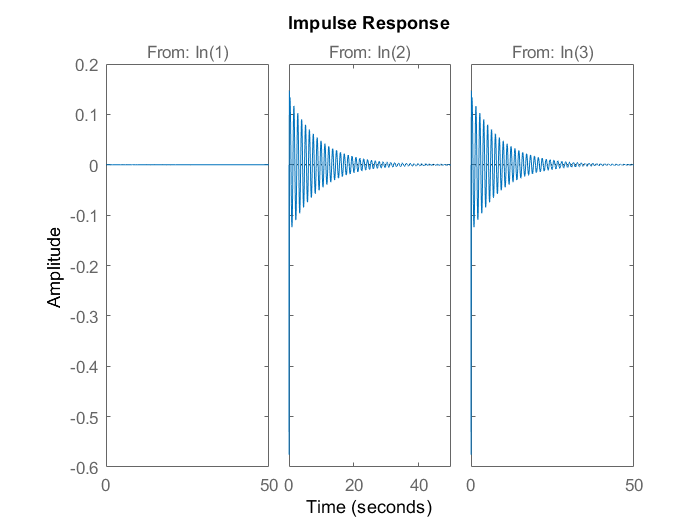

e = eig (A)

isAlways(e<zeros(4,1))

We got asymptotic stability that implies BIBO stability so this part of the stability is proven.

Now we have to consider Lyapunov stability as well. Lyapunov stability theorem has three main conditions:

- V > 0, if $x \ne x^*, V(x^*)=0
$

- V continuously differentiable

- V non-increasing, $V'(x) = grad(V)x'\leq0$

%we need a lyapunov function

ANALYSIS - CONTROLLABILITY, OBSERVABILITY

First we need to check controllability. Controllability means that we want to influence the state with appropriate input, knowing the model (setting the initial condition).

Our model is controllable if the controllability matrix: $C_n=[\matrix{B & AB & A^2B & ... & A^{n-1}B}]
$ is full-rank.

%[B A*B A*A*B A*A*A*B]
cm = ctrb(A,B)

The system is stable:


r = rank(cm)

ans = logical
   1


controllable = logical(r==length(cm))
c_subspace = colspace(sym(cm))

e =  -22.8847 +35.9120i
 -22.8847 -35.9120i
  -0.1072 + 5.2499i
  -0.1072 - 5.2499i


Then we need to check observability. Observability means that we need state information from the measurements(output), knowing the model(determining the initial condition).

om = obsv(A,C)

ans = 4×1 logical array
   1
   1
   1
   1


r = rank(om)
observabl = logical(r==length(om))
% uo_subspace = null(sym(om))

ANALYSIS - DISCRETIZATION

Discretization of a linear state space model is the transformation of continuous differential equations into discrete difference equations, suitable for numerical computing.

For transforming a continuous function into a piecewise constant signal we use zero order hold sampling in which the key point is that the sampled signal is kept constant between two sampling instants.

We need to use the following equations:

- state equation: x(k+1) = $\Phi$x(k) + $\Gamma$u(k)

- output equation: y(k) = Cx(k) + Du(k)

cm = 	1.0e+06 *

         0         0         0    0.0000         0         0   -0.0000    0.0000    0.0000   -0.0000    0.0012    0.0012
         0         0         0         0    0.0000    0.0000    0.0000   -0.0022   -0.0022    0.0000    0.0136    0.0136
    0.0000         0         0   -0.0000    0.0000    0.0000   -0.0000    0.0012    0.0012    0.0000   -0.0673   -0.0673
         0    0.0000    0.0000    0.0000   -0.0022   -0.0022    0.0000    0.0136    0.0136   -0.0000    3.2806    3.2806


r = 4

controllable = logical
   0


$$c\_subspace = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

om = 	1.0e+04 *

    0.0001   -0.0001         0         0
         0         0    0.0001   -0.0001
   -0.0282    0.1845   -0.0001    0.0046
    1.1535   -8.3385   -0.0232   -0.0264


r = 4

observabl = logical
   1
